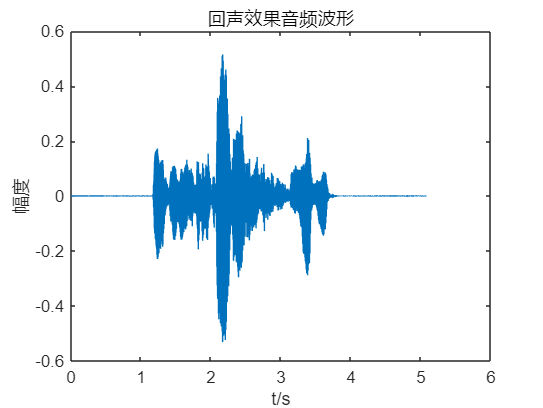

% 清除工作区和命令窗口
clc;clear;

% 读取音频文件
[y,Fs] = audioread('dspx1.wav');    % y为音频数据，Fs为采样频率
n = length(y);                      % 获取原始音频长度

% 设置回声参数
delay = 10000;                      % 设置延迟点数（控制回声延迟时间）
                                   % 实际延迟时间 = delay/Fs 秒

% 创建回声信号
a = zeros(n+delay,1);              % 创建一个比原始信号长delay个采样点的零向量
a(delay+1:n+delay) = 0.5.*y;       % 将原始信号延迟delay个点，并衰减到原来的0.5倍

% 扩展原始信号长度，使其与回声信号等长
y(n+delay,:) = 0;                  % 在原始信号末尾补零，使其长度与回声信号相同

% 将原始信号和回声信号叠加
y = y + a;                         % 将原始信号和回声信号相加

% 生成时间轴
t = (0:length(y)-1) / Fs;          % 计算时间序列，单位为秒

% 播放带有回声效果的音频
sound(y, Fs);                      % 使用原始采样频率播放处理后的音频

% 绘制带回声效果的音频波形
figure;
plot(t, y);
title('回声效果音频波形');
xlabel('t/s');
ylabel('幅度');

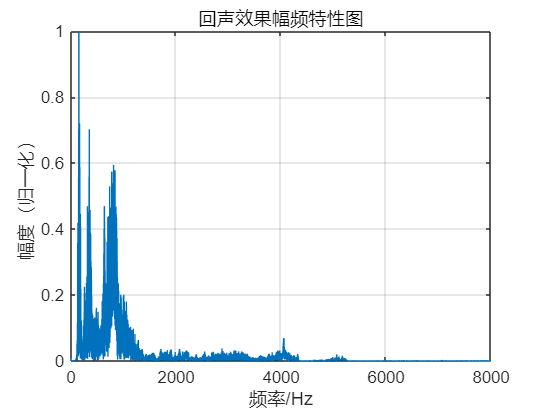


% 添加幅频特性分析
figure;
Y = fft(y);                      % 对带回声信号进行FFT
M = max(Y);                      % 获取最大值用于归一化
f = (0:length(y)-1)*Fs/length(y);% 计算频率向量
Y = abs(Y)/abs(M);              % 幅度归一化处理

% 绘制频谱图
plot(f, Y);
title('回声效果幅频特性图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);                 % 限制频率显示范围
grid on;                        % 添加网格便于观察